clearvars
close all
clc

global ax2
global ax1

osrm_data_sp = load('output_data\osrm_output_with_speed.mat').out;
aug_data = load('output_data\aug_output.mat').aug_data;
segments = load('input_data\osm.mat').osm;
markers = load('input_data\markers.mat').markers;
% adding distance from origin column to aug_out
[~,b] = ismember(aug_data.segment_id,segments.segment_id);
aug_data.distance_from_start = segments.distance_from_start(b);

corridor_length = 1e-3 * max(sum(segments(segments.dir==2,:).calc_length) , sum(segments(segments.dir==1,:).calc_length));
osrm_data_sp.Properties.VariableNames{10} = 'dir';
osrm_data_sp.Properties.VariableNames{11} = 'segment_id';
aug_data.Properties.VariableNames{2} = 'time';
osrm_data_sp.Properties.VariableNames{4} = 'time';

aux_segments = unique(aug_data.segment_id);
filter = NaN(size(aug_data,1),1);
for i=1:1:length(aux_segments)
    filter(aug_data.segment_id == aux_segments(i)) = isoutlier(aug_data(aug_data.segment_id == aux_segments(i),:).speed,'quartiles');
end
aug_data.filter = ~logical(filter);
size(aug_data,1)

ans = 114587

sum(filter)

ans = 2669


aux_segments = unique(osrm_data_sp.segment_id);
filter = NaN(size(osrm_data_sp,1),1);
for i=1:1:length(aux_segments)
    filter(osrm_data_sp.segment_id == aux_segments(i)) = isoutlier(osrm_data_sp(osrm_data_sp.segment_id == aux_segments(i),:).speed,'quartiles');
end
osrm_data_sp.filter = ~logical(filter);
size(osrm_data_sp,1)

ans = 114833

sum(filter)

ans = 3666

aug_data = aug_data(aug_data.filter,:);
osrm_data_sp = osrm_data_sp(osrm_data_sp.filter,:);

gross_data = [aug_data(:,{'segment_id','time','arac_id','dir','speed','route_id','distance_from_start','filter'}) ; osrm_data_sp(:,{'segment_id','time','arac_id','dir','speed','route_id','distance_from_start','filter'})];



[GC,GR] = findgroups(gross_data.segment_id);
b = ismember(segments.segment_id,GR);

segments.q1 = NaN(size(segments.segment_id,1),1);
segments.q2 = NaN(size(segments.segment_id,1),1);
segments.q3 = NaN(size(segments.segment_id,1),1);

segments.q3(b) = splitapply(@(x) quantile(x,0.75),gross_data.speed,GC);
segments.q2(b) = splitapply(@(x) quantile(x,0.5),gross_data.speed,GC);
segments.q1(b) = splitapply(@(x) quantile(x,0.25),gross_data.speed,GC);


[GC,GR] = findgroups(aug_data.segment_id);
b = ismember(segments.segment_id,GR);

segments.q1_aug = NaN(size(segments.segment_id,1),1);
segments.q2_aug = NaN(size(segments.segment_id,1),1);
segments.q3_aug = NaN(size(segments.segment_id,1),1);

segments.q3_aug(b) = splitapply(@(x) quantile(x,0.75),aug_data.speed,GC);
segments.q2_aug(b) = splitapply(@(x) quantile(x,0.5),aug_data.speed,GC);
segments.q1_aug(b) = splitapply(@(x) quantile(x,0.25),aug_data.speed,GC);


% 
% [a1,a2] = groupcounts(gross_data.arac_id(gross_data.dir == 1));
% arac_list = sortrows(table(a1,a2),'a1','descend');
% get_arac = arac_list.a2(1:10); % get 10 vehicles with the most data
% 
% [b1,b2] = groupcounts(gross_data.arac_id(gross_data.dir == 2));
% arac_list2 = sortrows(table(b1,b2),'b1','descend');
% get_arac2 = arac_list2.b2(1:10); % get 10 vehicles with the most data



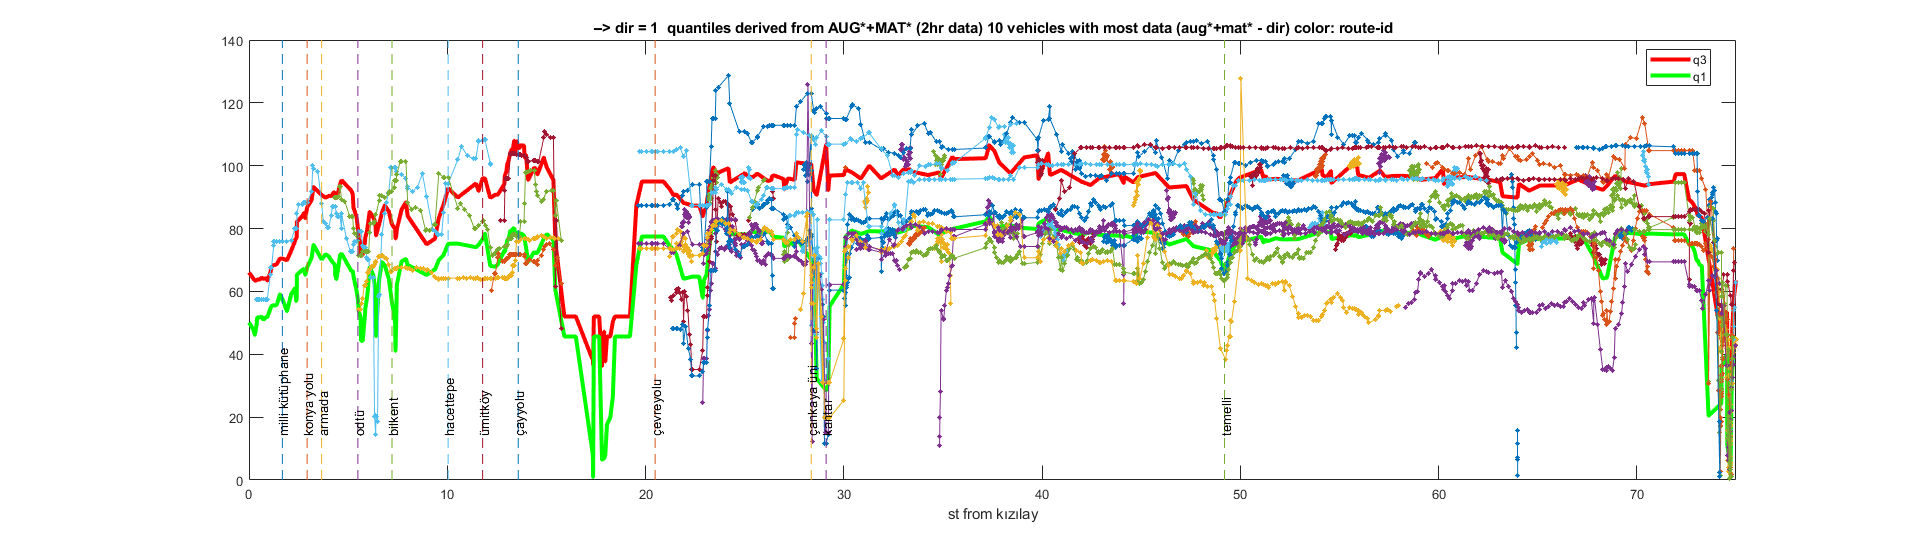

h = figure();


dir_chosen = 1;

[a1,a2] = groupcounts(gross_data.arac_id(gross_data.dir == dir_chosen));
arac_list = sortrows(table(a1,a2),'a1','descend');
get_arac = arac_list.a2(1:10); % get 10 vehicles with the most data

[~,GR] = findgroups(gross_data.segment_id);

b = ismember(segments.segment_id,GR);

index = b & segments.dir == dir_chosen;
ax1 = axes("Parent",h);
% ax1.YLim(1) = 0;
plot(ax1,segments.distance_from_start(index) * 1e-3 , segments.q3(index),'LineStyle',"-","Color",'r',"Marker","none","LineWidth",3,'MarkerSize',1);
% hold(ax1,'on')
% plot(ax1,segments.distance_from_start(index) * 1e-3, segments.q2(index),'LineStyle',":","Color",'b',"Marker","*","LineWidth",0.1,'MarkerSize',1);
hold(ax1,'on')
plot(ax1,segments.distance_from_start(index) * 1e-3, segments.q1(index),'LineStyle',"-","Color",'g',"Marker","none","LineWidth",3,'MarkerSize',1);
% hold(ax1,'on')
% scatter(ax1,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3, get_data.speed(get_data.dir == dir_chosen),5,'filled');

min_x = min(segments.distance_from_start(index) * 1e-3);
max_x = max(segments.distance_from_start(index) * 1e-3);
xlabel(ax1,'st from kızılay')
legend(ax1,'AutoUpdate','off');
legend(ax1,'q3','q1','Location',"best");
xlim(ax1,[min_x , max_x]);
title(ax1,'--> dir = 1  quantiles derived from AUG*+MAT* (2hr data) 10 vehicles with most data (aug*+mat* - dir) color: route-id')

for i=1:1:length(get_arac)
    get_data = gross_data(gross_data.arac_id == get_arac(i),:);
    get_data = sortrows(get_data,{'route_id','time'});
    G = findgroups(get_data.route_id(get_data.dir == dir_chosen));
    if ~isempty(G)
        hold(ax1,'on')
        splitapply(@myplot1,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3,get_data.speed(get_data.dir == dir_chosen),G)
    end
    
%     scatter(ax1,get_data.distance_from_start(get_data.dir == 1) * 1e-3, get_data.speed(get_data.dir == 1),7,'filled');
%     hold(ax2,'on')
%     scatter(ax2,get_data.distance_from_start(get_data.dir == 2) * 1e-3, get_data.speed(get_data.dir == 2),2,'filled');
end
yLimits = get(ax1,'YLim');
line(ax1,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax1, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.1*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
set(h,'Units','normalized','Position',[0 0 1 0.5]);

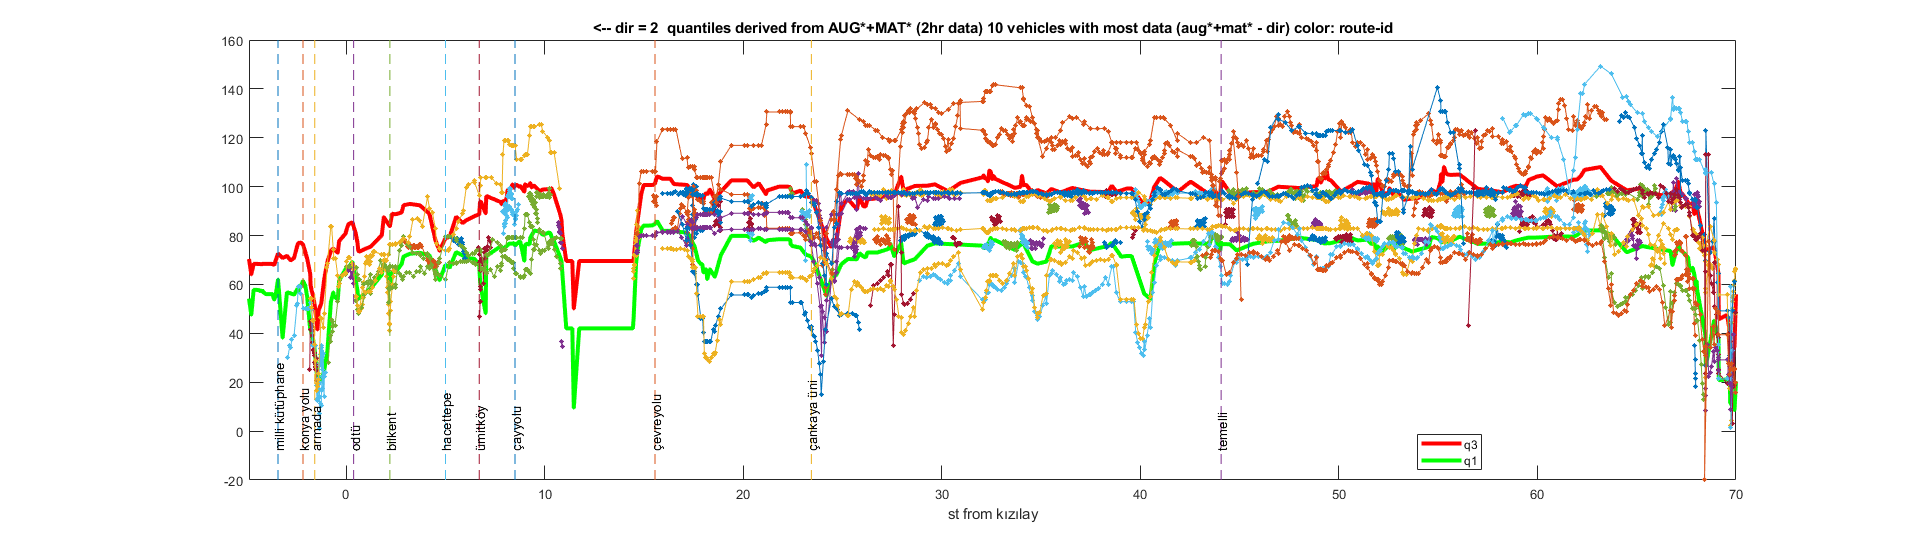

h2=figure();

dir_chosen = 2;

[a1,a2] = groupcounts(gross_data.arac_id(gross_data.dir == dir_chosen));
arac_list = sortrows(table(a1,a2),'a1','descend');
get_arac = arac_list.a2(1:10); % get 10 vehicles with the most data

[~,GR] = findgroups(gross_data.segment_id);

b = ismember(segments.segment_id,GR);

index = b & segments.dir == dir_chosen;
ax2 = axes("Parent",h2);
ax2.YLim(1) = 0;
plot(ax2,segments.distance_from_start(index) * 1e-3 , segments.q3(index),'LineStyle',"-","Color",'r',"Marker","none","LineWidth",3,'MarkerSize',1);
% hold(ax2,'on')
% plot(ax2,segments.distance_from_start(index) * 1e-3, segments.q2(index),'LineStyle',":","Color",'b',"Marker","*","LineWidth",0.1,'MarkerSize',1);
hold(ax2,'on')
plot(ax2,segments.distance_from_start(index) * 1e-3, segments.q1(index),'LineStyle',"-","Color",'g',"Marker","none","LineWidth",3,'MarkerSize',1);
% hold(ax2,'on')
% scatter(ax2,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3, get_data.speed(get_data.dir == dir_chosen),7,'filled');
% 

for i=1:1:length(get_arac)
    get_data = gross_data(gross_data.arac_id == get_arac(i),:);
    get_data = sortrows(get_data,{'route_id','time'});
%     hold(ax1,'on')
%     scatter(ax1,get_data.distance_from_start(get_data.dir == 1) * 1e-3, get_data.speed(get_data.dir == 1),2,'filled');
    hold(ax2,'on')
%     scatter(ax2,get_data.distance_from_start(get_data.dir == 2) * 1e-3, get_data.speed(get_data.dir == 2),7,'filled');
%     plot(ax2,get_data.distance_from_start(get_data.dir == 2) * 1e-3, get_data.speed(get_data.dir == 2),"Marker","*","MarkerSize",1);
    G = findgroups(get_data.route_id(get_data.dir == dir_chosen));
    if ~isempty(G)
        splitapply(@myplot2,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3,get_data.speed(get_data.dir == dir_chosen),G)
    end
%     plot_arac(get_data,ax2);
end

set(h2,'Units','normalized','Position',[0 0 1 0.5]);
min_x = min(segments.distance_from_start(index) * 1e-3);
max_x = max(segments.distance_from_start(index) * 1e-3);
xlabel('st from kızılay')
legend(ax2,'AutoUpdate','off');
legend('q3','q1','Location',"best");
xlim(ax2,[min_x , max_x]);
ax2.XDir = "reverse";
set(ax2, 'XTickLabel', flip(ax2.XTickLabel));
yLimits = get(ax2,'YLim');
line(ax2,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax2, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), -0.05*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
title(ax2,'<-- dir = 2  quantiles derived from AUG*+MAT* (2hr data) 10 vehicles with most data (aug*+mat* - dir) color: route-id')

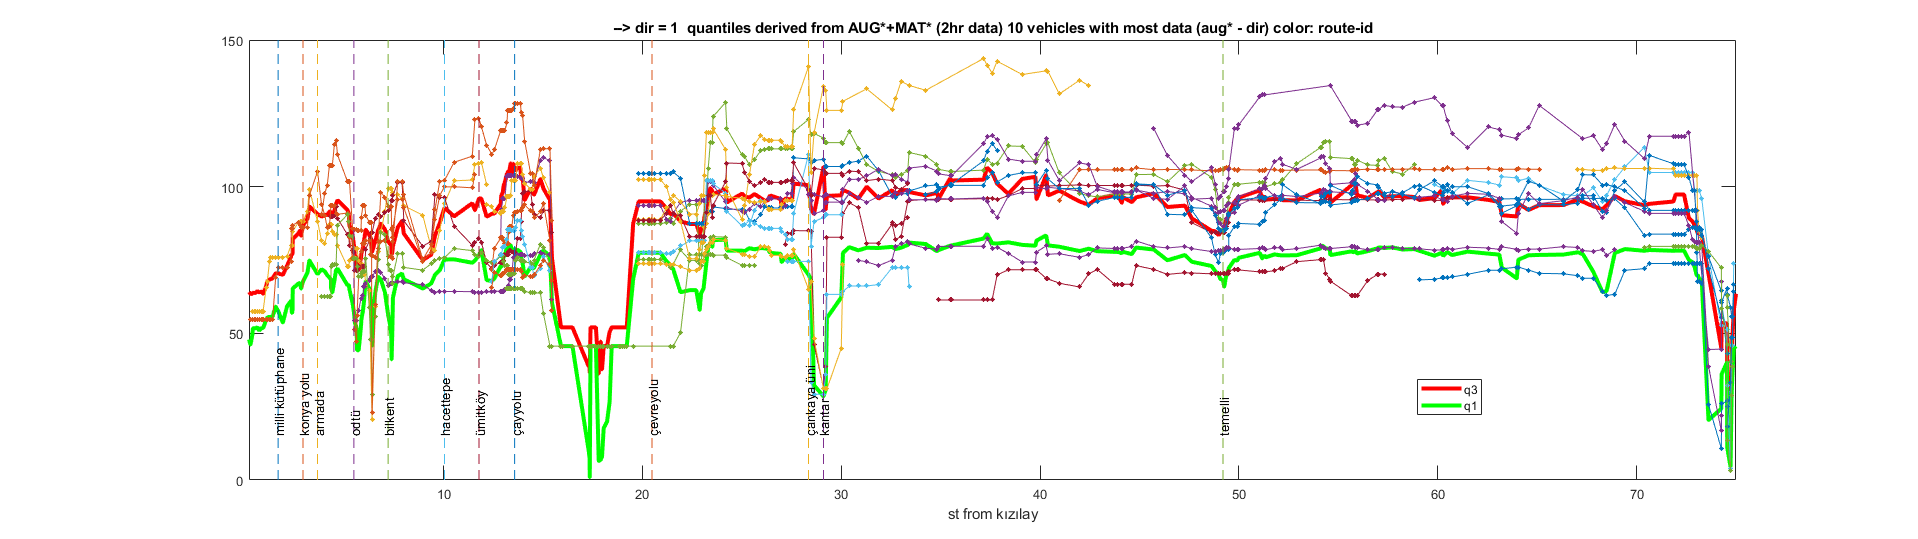

h = figure();


dir_chosen = 1;

[a1,a2] = groupcounts(aug_data.arac_id(aug_data.dir == dir_chosen));
arac_list = sortrows(table(a1,a2),'a1','descend');
get_arac = arac_list.a2(1:10); % get 10 vehicles with the most data

[~,GR] = findgroups(aug_data.segment_id);

b = ismember(segments.segment_id,GR);

index = b & segments.dir == dir_chosen;
ax1 = axes("Parent",h);
% ax1.YLim(1) = 0;
plot(ax1,segments.distance_from_start(index) * 1e-3 , segments.q3(index),'LineStyle',"-","Color",'r',"Marker","none","LineWidth",3,'MarkerSize',1);
% hold(ax1,'on')
% plot(ax1,segments.distance_from_start(index) * 1e-3, segments.q2(index),'LineStyle',":","Color",'b',"Marker","*","LineWidth",0.1,'MarkerSize',1);
hold(ax1,'on')
plot(ax1,segments.distance_from_start(index) * 1e-3, segments.q1(index),'LineStyle',"-","Color",'g',"Marker","none","LineWidth",3,'MarkerSize',1);
% hold(ax1,'on')
% scatter(ax1,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3, get_data.speed(get_data.dir == dir_chosen),5,'filled');

min_x = min(segments.distance_from_start(index) * 1e-3);
max_x = max(segments.distance_from_start(index) * 1e-3);
xlabel(ax1,'st from kızılay')
legend(ax1,'AutoUpdate','off');
legend(ax1,'q3','q1','Location',"best");
xlim(ax1,[min_x , max_x]);
title(ax1,'--> dir = 1  quantiles derived from AUG*+MAT* (2hr data) 10 vehicles with most data (aug* - dir) color: route-id')

for i=1:1:length(get_arac)
    get_data = aug_data(aug_data.arac_id == get_arac(i),:);
    get_data = sortrows(get_data,{'route_id','time'});
    G = findgroups(get_data.route_id(get_data.dir == dir_chosen));
    if ~isempty(G)
        hold(ax1,'on')
        splitapply(@myplot1,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3,get_data.speed(get_data.dir == dir_chosen),G)
    end
    
%     scatter(ax1,get_data.distance_from_start(get_data.dir == 1) * 1e-3, get_data.speed(get_data.dir == 1),7,'filled');
%     hold(ax2,'on')
%     scatter(ax2,get_data.distance_from_start(get_data.dir == 2) * 1e-3, get_data.speed(get_data.dir == 2),2,'filled');
end
yLimits = get(ax1,'YLim');
line(ax1,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax1, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.1*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
set(h,'Units','normalized','Position',[0 0 1 0.5]);

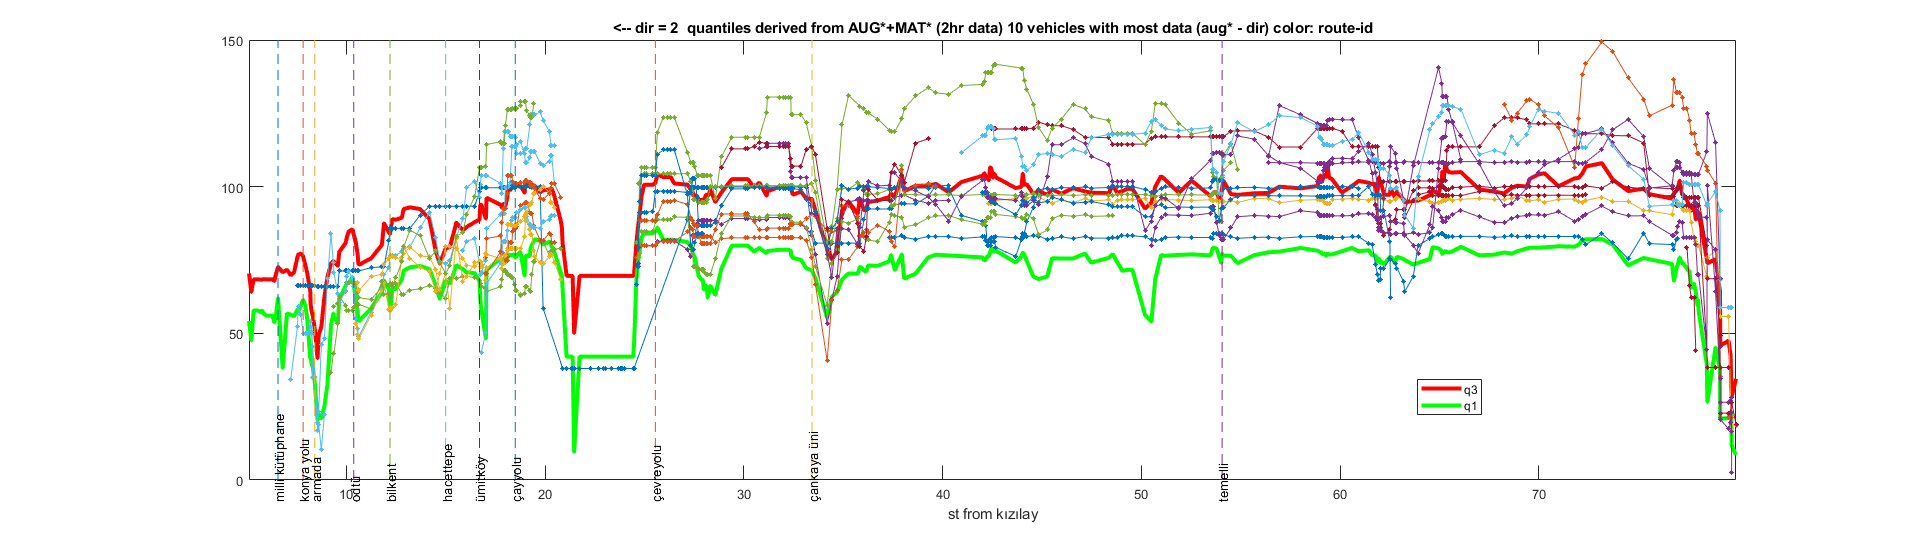

h2=figure();

dir_chosen = 2;

[a1,a2] = groupcounts(aug_data.arac_id(aug_data.dir == dir_chosen));
arac_list = sortrows(table(a1,a2),'a1','descend');
get_arac = arac_list.a2(1:10); % get 10 vehicles with the most data

[~,GR] = findgroups(aug_data.segment_id);

b = ismember(segments.segment_id,GR);

index = b & segments.dir == dir_chosen;
ax2 = axes("Parent",h2);
ax2.YLim(1) = 0;
plot(ax2,segments.distance_from_start(index) * 1e-3 , segments.q3(index),'LineStyle',"-","Color",'r',"Marker","none","LineWidth",3,'MarkerSize',1);
% hold(ax2,'on')
% plot(ax2,segments.distance_from_start(index) * 1e-3, segments.q2(index),'LineStyle',":","Color",'b',"Marker","*","LineWidth",0.1,'MarkerSize',1);
hold(ax2,'on')
plot(ax2,segments.distance_from_start(index) * 1e-3, segments.q1(index),'LineStyle',"-","Color",'g',"Marker","none","LineWidth",3,'MarkerSize',1);
% hold(ax2,'on')
% scatter(ax2,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3, get_data.speed(get_data.dir == dir_chosen),7,'filled');
% 

for i=1:1:length(get_arac)
    get_data = aug_data(aug_data.arac_id == get_arac(i),:);
    get_data = sortrows(get_data,{'route_id','time'});
%     hold(ax1,'on')
%     scatter(ax1,get_data.distance_from_start(get_data.dir == 1) * 1e-3, get_data.speed(get_data.dir == 1),2,'filled');
    hold(ax2,'on')
%     scatter(ax2,get_data.distance_from_start(get_data.dir == 2) * 1e-3, get_data.speed(get_data.dir == 2),7,'filled');
%     plot(ax2,get_data.distance_from_start(get_data.dir == 2) * 1e-3, get_data.speed(get_data.dir == 2),"Marker","*","MarkerSize",1);
    G = findgroups(get_data.route_id(get_data.dir == dir_chosen));
    if ~isempty(G)
        splitapply(@myplot2,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3,get_data.speed(get_data.dir == dir_chosen),G)
    end
%     plot_arac(get_data,ax2);
end

set(h2,'Units','normalized','Position',[0 0 1 0.5]);
min_x = min(segments.distance_from_start(index) * 1e-3);
max_x = max(segments.distance_from_start(index) * 1e-3);
xlabel('st from kızılay')
legend(ax2,'AutoUpdate','off');
legend('q3','q1','Location',"best");
xlim(ax2,[min_x , max_x]);
ax2.XDir = "reverse";
set(ax2, 'XTickLabel', flip(ax2.XTickLabel));
yLimits = get(ax2,'YLim');
line(ax2,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax2, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), -0.05*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
title(ax2,'<-- dir = 2  quantiles derived from AUG*+MAT* (2hr data) 10 vehicles with most data (aug* - dir) color: route-id')

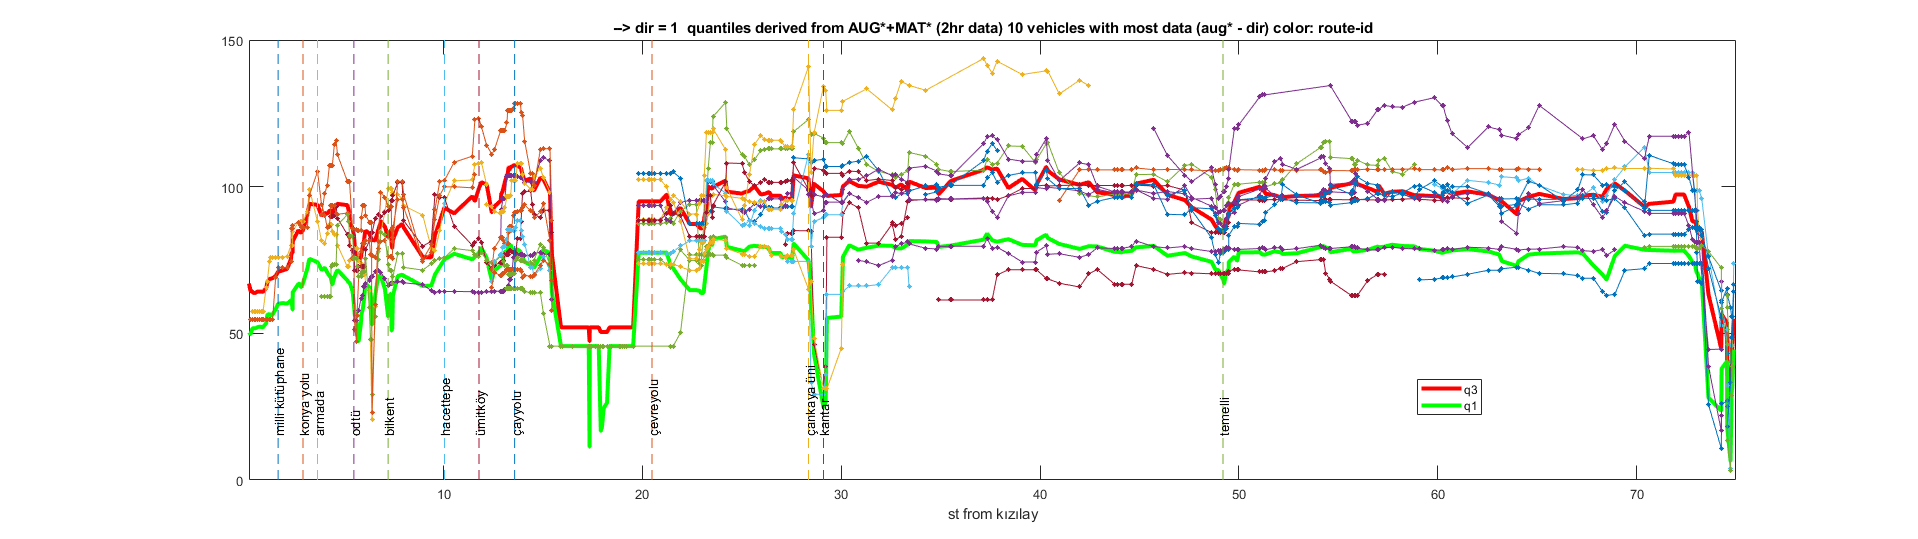

h = figure();


dir_chosen = 1;

[a1,a2] = groupcounts(aug_data.arac_id(aug_data.dir == dir_chosen));
arac_list = sortrows(table(a1,a2),'a1','descend');
get_arac = arac_list.a2(1:10); % get 10 vehicles with the most data

[~,GR] = findgroups(aug_data.segment_id);

b = ismember(segments.segment_id,GR);

index = b & segments.dir == dir_chosen;
ax1 = axes("Parent",h);
% ax1.YLim(1) = 0;
plot(ax1,segments.distance_from_start(index) * 1e-3 , segments.q3_aug(index),'LineStyle',"-","Color",'r',"Marker","none","LineWidth",3,'MarkerSize',1);
% hold(ax1,'on')
% plot(ax1,segments.distance_from_start(index) * 1e-3, segments.q2(index),'LineStyle',":","Color",'b',"Marker","*","LineWidth",0.1,'MarkerSize',1);
hold(ax1,'on')
plot(ax1,segments.distance_from_start(index) * 1e-3, segments.q1_aug(index),'LineStyle',"-","Color",'g',"Marker","none","LineWidth",3,'MarkerSize',1);
% hold(ax1,'on')
% scatter(ax1,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3, get_data.speed(get_data.dir == dir_chosen),5,'filled');

min_x = min(segments.distance_from_start(index) * 1e-3);
max_x = max(segments.distance_from_start(index) * 1e-3);
xlabel(ax1,'st from kızılay')
legend(ax1,'AutoUpdate','off');
legend(ax1,'q3','q1','Location',"best");
xlim(ax1,[min_x , max_x]);
title(ax1,'--> dir = 1  quantiles derived from AUG*+MAT* (2hr data) 10 vehicles with most data (aug* - dir) color: route-id')

for i=1:1:length(get_arac)
    get_data = aug_data(aug_data.arac_id == get_arac(i),:);
    get_data = sortrows(get_data,{'route_id','time'});
    G = findgroups(get_data.route_id(get_data.dir == dir_chosen));
    if ~isempty(G)
        hold(ax1,'on')
        splitapply(@myplot1,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3,get_data.speed(get_data.dir == dir_chosen),G)
    end
    
%     scatter(ax1,get_data.distance_from_start(get_data.dir == 1) * 1e-3, get_data.speed(get_data.dir == 1),7,'filled');
%     hold(ax2,'on')
%     scatter(ax2,get_data.distance_from_start(get_data.dir == 2) * 1e-3, get_data.speed(get_data.dir == 2),2,'filled');
end
yLimits = get(ax1,'YLim');
line(ax1,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax1, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.1*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
set(h,'Units','normalized','Position',[0 0 1 0.5]);

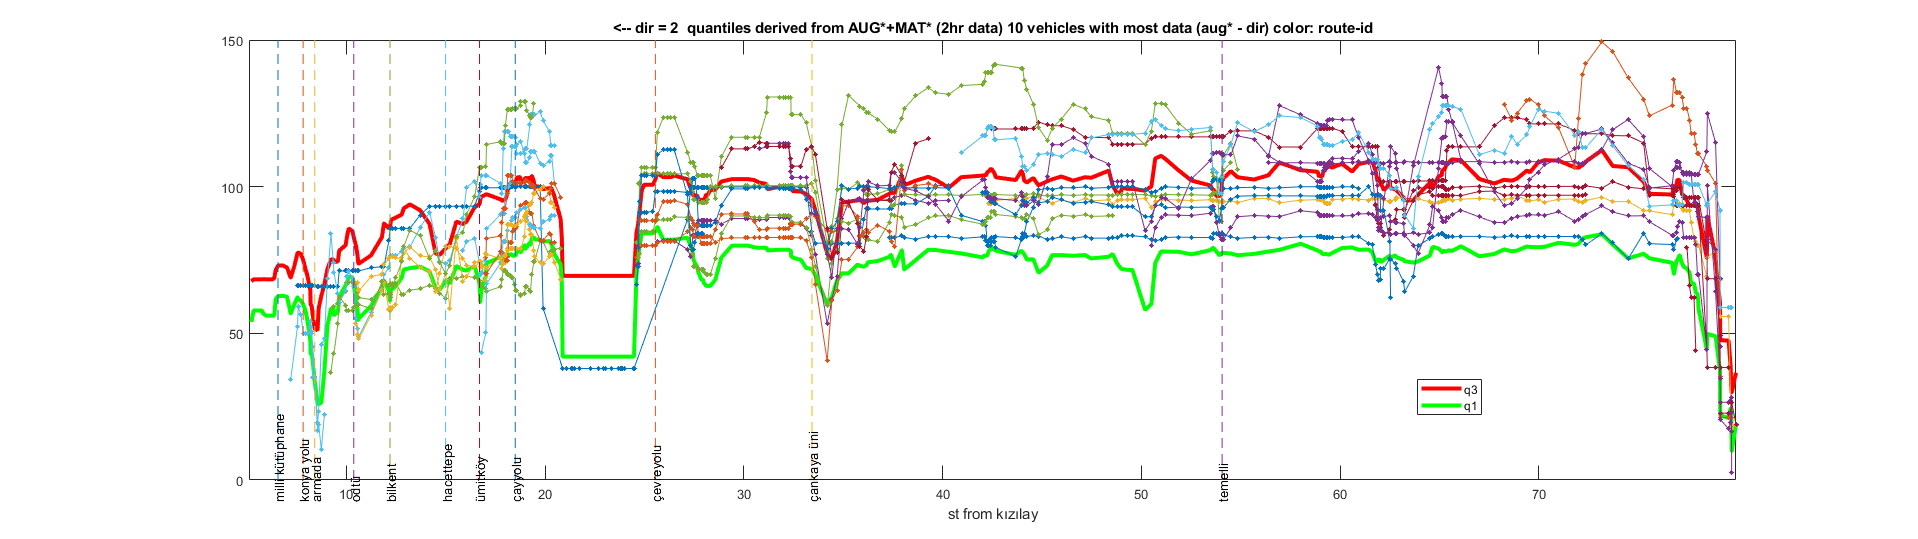

h2=figure();

dir_chosen = 2;

[a1,a2] = groupcounts(aug_data.arac_id(aug_data.dir == dir_chosen));
arac_list = sortrows(table(a1,a2),'a1','descend');
get_arac = arac_list.a2(1:10); % get 10 vehicles with the most data

[~,GR] = findgroups(aug_data.segment_id);

b = ismember(segments.segment_id,GR);

index = b & segments.dir == dir_chosen;
ax2 = axes("Parent",h2);
ax2.YLim(1) = 0;
plot(ax2,segments.distance_from_start(index) * 1e-3 , segments.q3_aug(index),'LineStyle',"-","Color",'r',"Marker","none","LineWidth",3,'MarkerSize',1);
% hold(ax2,'on')
% plot(ax2,segments.distance_from_start(index) * 1e-3, segments.q2(index),'LineStyle',":","Color",'b',"Marker","*","LineWidth",0.1,'MarkerSize',1);
hold(ax2,'on')
plot(ax2,segments.distance_from_start(index) * 1e-3, segments.q1_aug(index),'LineStyle',"-","Color",'g',"Marker","none","LineWidth",3,'MarkerSize',1);
% hold(ax2,'on')
% scatter(ax2,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3, get_data.speed(get_data.dir == dir_chosen),7,'filled');
% 

for i=1:1:length(get_arac)
    get_data = aug_data(aug_data.arac_id == get_arac(i),:);
    get_data = sortrows(get_data,{'route_id','time'});
%     hold(ax1,'on')
%     scatter(ax1,get_data.distance_from_start(get_data.dir == 1) * 1e-3, get_data.speed(get_data.dir == 1),2,'filled');
    hold(ax2,'on')
%     scatter(ax2,get_data.distance_from_start(get_data.dir == 2) * 1e-3, get_data.speed(get_data.dir == 2),7,'filled');
%     plot(ax2,get_data.distance_from_start(get_data.dir == 2) * 1e-3, get_data.speed(get_data.dir == 2),"Marker","*","MarkerSize",1);
    G = findgroups(get_data.route_id(get_data.dir == dir_chosen));
    if ~isempty(G)
        splitapply(@myplot2,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3,get_data.speed(get_data.dir == dir_chosen),G)
    end
%     plot_arac(get_data,ax2);
end

set(h2,'Units','normalized','Position',[0 0 1 0.5]);
min_x = min(segments.distance_from_start(index) * 1e-3);
max_x = max(segments.distance_from_start(index) * 1e-3);
xlabel('st from kızılay')
legend(ax2,'AutoUpdate','off');
legend('q3','q1','Location',"best");
xlim(ax2,[min_x , max_x]);
ax2.XDir = "reverse";
set(ax2, 'XTickLabel', flip(ax2.XTickLabel));
yLimits = get(ax2,'YLim');
line(ax2,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax2, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), -0.05*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
title(ax2,'<-- dir = 2  quantiles derived from AUG*+MAT* (2hr data) 10 vehicles with most data (aug* - dir) color: route-id')

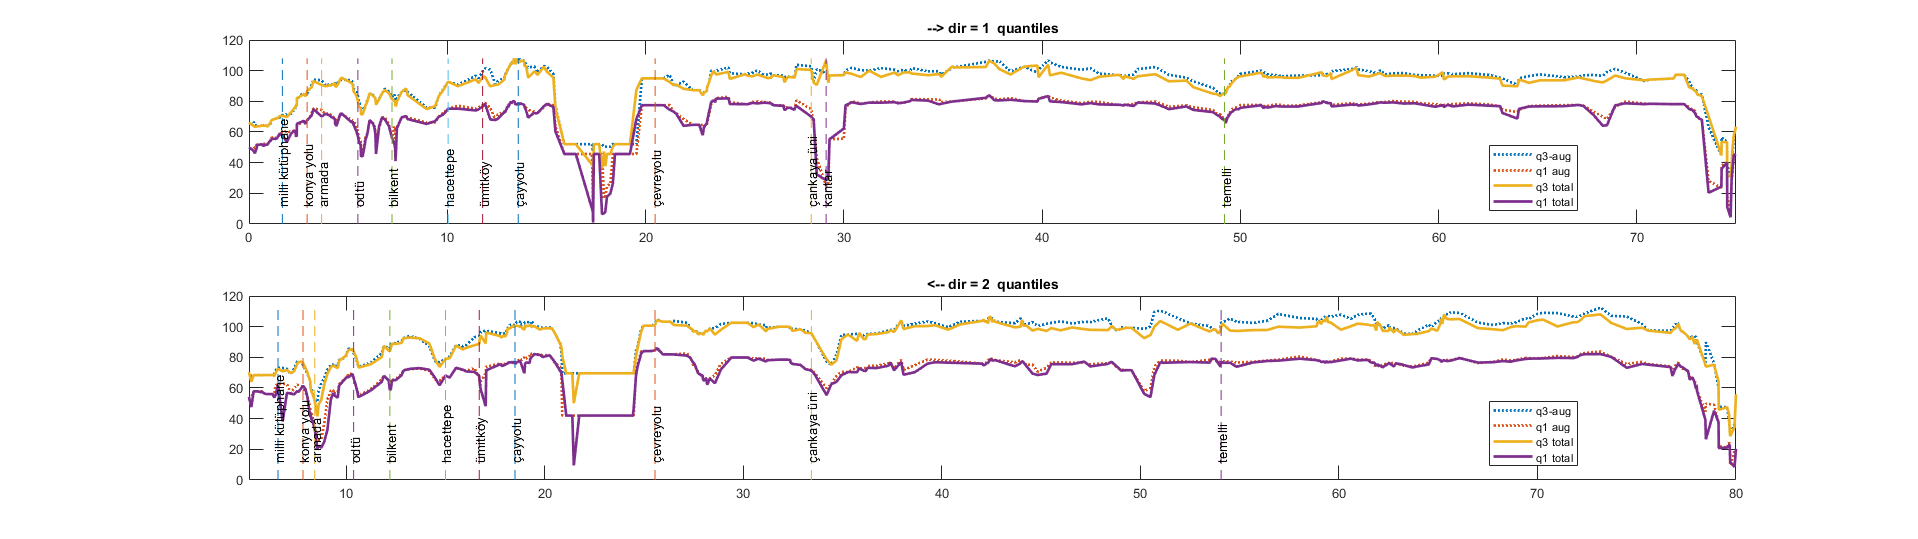

h = figure();


dir_chosen = 1;


a = subplot(2,1,1);
index = segments.dir == dir_chosen;
plot(a,segments.distance_from_start(index) * 1e-3 , segments.q3_aug(index),'LineStyle',":",'LineWidth',2);
hold on
plot(a,segments.distance_from_start(index) * 1e-3, segments.q1_aug(index),'LineStyle',":",'LineWidth',2);
hold on
plot(a,segments.distance_from_start(index) * 1e-3 , segments.q3(index),'LineStyle',"-",'LineWidth',2);
hold on
plot(a,segments.distance_from_start(index) * 1e-3 , segments.q1(index),'LineStyle',"-",'LineWidth',2);
legend(a,'AutoUpdate','off')
legend(a,'q3-aug','q1 aug','q3 total','q1 total','Location','Best')

min_x = min(segments.distance_from_start(index) * 1e-3);
max_x = max(segments.distance_from_start(index) * 1e-3);
% xlabel(a,'st from kızılay')
% legend(a,'AutoUpdate','off');
% legend(a,'q3','q1','Location',"best");
xlim(a,[min_x , max_x]);
title(a,'--> dir = 1  quantiles')

yLimits = get(a,'YLim');
line(a,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(a, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.1*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);

b = subplot(2,1,2);
dir_chosen = 2;
index = segments.dir == dir_chosen;
plot(b,segments.distance_from_start(index) * 1e-3 , segments.q3_aug(index),'LineStyle',":",'LineWidth',2);
hold on
plot(b,segments.distance_from_start(index) * 1e-3, segments.q1_aug(index),'LineStyle',":",'LineWidth',2);
hold on
plot(b,segments.distance_from_start(index) * 1e-3 , segments.q3(index),'LineStyle',"-",'LineWidth',2);
hold on
plot(b,segments.distance_from_start(index) * 1e-3 , segments.q1(index),'LineStyle',"-",'LineWidth',2);
legend(b,'AutoUpdate','off')
legend(b,'q3-aug','q1 aug','q3 total','q1 total','Location','Best')
% hold(ax1,'on')
% scatter(ax1,get_data.distance_from_start(get_data.dir == dir_chosen) * 1e-3, get_data.speed(get_data.dir == dir_chosen),5,'filled');

min_x = min(segments.distance_from_start(index) * 1e-3);
max_x = max(segments.distance_from_start(index) * 1e-3);
b.XDir = "reverse";
set(b, 'XTickLabel', flip(b.XTickLabel));
xlim(b,[min_x , max_x]);
title(b,'<-- dir = 2  quantiles')

yLimits = get(b,'YLim');
line(b,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(b, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.1*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
set(h,'Units','normalized','Position',[0 0 1 0.5]);

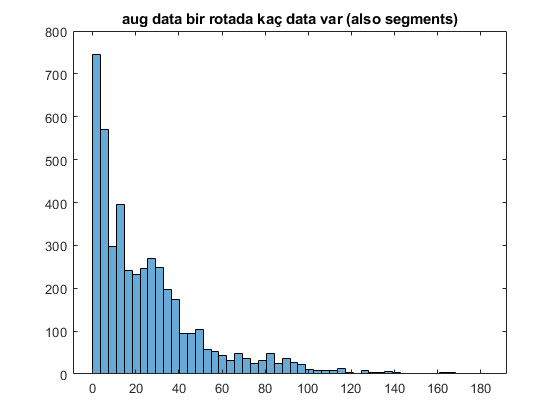

c = groupcounts(aug_data,{'arac_id','route_id'});

h=figure();

histogram(c.GroupCount,50);
title('aug data bir rotada kaç data var (also segments)')

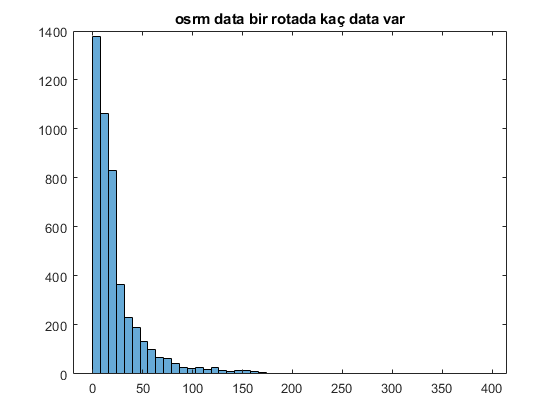

c = groupcounts(osrm_data_sp,{'arac_id','route_id'});

h=figure();

histogram(c.GroupCount,50);
title('osrm data bir rotada kaç data var')

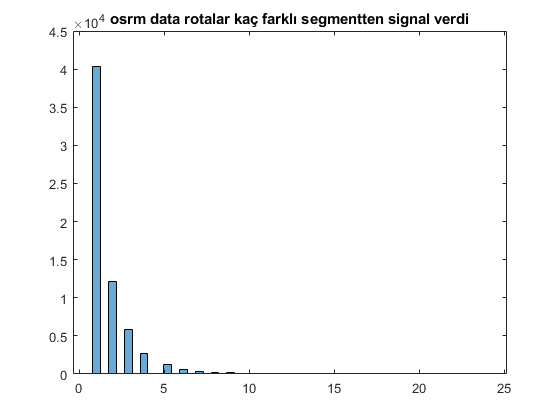

c = groupcounts(osrm_data_sp,{'arac_id','route_id','segment_id'});

h=figure();

histogram(c.GroupCount,50);
title('osrm data rotalar kaç farklı segmentten signal verdi')

find( c.GroupCount == max(c.GroupCount))

ans = 37921

function myplot2(space,speed)
    global ax2
    plot(ax2,space,speed,'Marker',"*",'MarkerSize',3);
end
function myplot1(space,speed)
    global ax1
    plot(ax1,space,speed,'Marker',"*",'MarkerSize',3);
end